# MATools Data Processing Example

## *Bjorn Saltzmann*

This example shows how to perform common operations on ARPES image data using the functions of the MATools toolkit.

For a more in-depth explanation of potential in- and output of those functions, consult the UserGuide.

## Reading in Data

A datafile in the HDF5 or SP format can be read using the *ReadARPES* function. The function will return all data from the specified file in the order shown in the command below.

The process is confirmed in the MATLAB command window by displaying "-Reading in data" as shown.

[Angle,Energy,Scan,Data,ep,Note]=ReadARPES('014_FS.h5');

- Reading in 014_FS.h5


The 'Note' contains information about the ARPES setup. The *disp* command below displays this information in the MATLAB command window.

The data has already been corrected for curvature introduced in the energy analyser as well as aligned at the Fermi level.

Note how in this case, the tilt is given as a range in MATLAB syntax. This will be the case for whatever quantity was measured in Scan.

disp(Note)

hv      = 632
Pol     = LV
Slit    = 20
Mode    = MAM
Epass   = 100
Ek/Eb   = Eb
Energy  = -2
dt      = 10
Theta   = 6.7475
Tilt    = -1.5:0.1:5.5
Azimuth = -166.2518
X       = 0.4503
Z       = -0.3956
Comment = 
Corr    = true
Grating  = 800
Temp     = 6.16
Y        = -0.200



## Displaying the Data

First we select one of the frames at a certain tilt angle, the 20th in this example, and then display it using the *ImData* function and the colormap option 'hot'. The *ImData* function will be used throughout this example to create heatmap-style plots. Since it creates a regular MATLAB figure via the *pcolor* function, all figure-modifying MATLAB commands such as *colormap* can be used on its output.

A scale can be included using the 'colorbar' command.

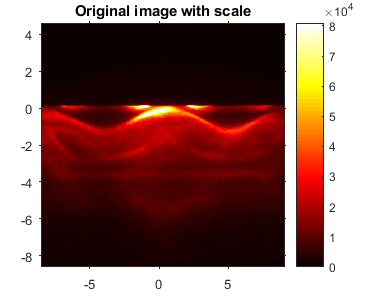

nFrame=20; DataFrame=Data(:,:,nFrame);

figure; ImData(Angle,Energy,DataFrame,'Flat'); 
colormap hot; set(gca,'TickDir','Out');
title('Original image with scale');colorbar;set(gcf,'Position',[0,0,380,300])

Grayscale images can be produced using the colormap option 'gray'.

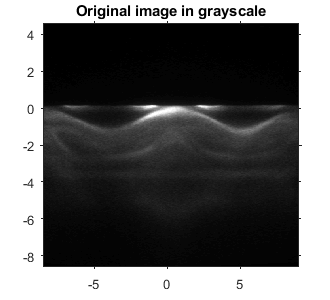

figure; ImData(Angle,Energy,DataFrame,'Flat'); 
colormap gray; set(gca,'TickDir','Out');
title('Original image in grayscale');set(gcf,'Position',[0,0,330,300])

## Processing the Image

We use the function *SetContrast* to set the value of the least intense 50% of points to 0 and the intensity of the most intense 0.2% to 1 for the selected frame and display the result in comparison to the original. This results in enhanced contrast as shown in the images below.

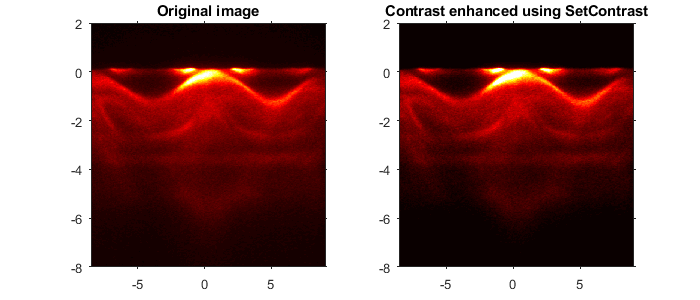

ContDataFrame=SetContrast(DataFrame,0.5,0.998);

figure;subplot(121);ImData(Angle,Energy,DataFrame,'Flat');
colormap hot; set(gca,'TickDir','Out'); limit2=[-8,2]; ylim(limit2)
title('Original image')

subplot(122);ImData(Angle,Energy,ContDataFrame,'Flat');
colormap hot; set(gca,'TickDir','Out'); ylim(limit2)
title('Contrast enhanced using SetContrast');set(gcf,'Position',[0,0,700,300])

The contrast may also be increased by changing the gamma value from its default of 1 by using a third argument to *SetContrast.*

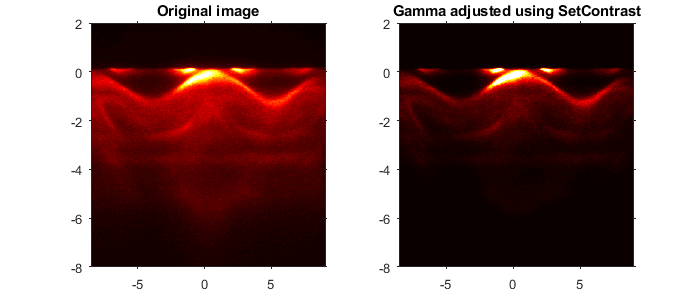

ContDataFrame=SetContrast(DataFrame,0.45,0.998,1.6);

figure;subplot(121);ImData(Angle,Energy,DataFrame,'Flat');
colormap hot; set(gca,'TickDir','Out'); ylim(limit2);
title('Original image')

subplot(122); ImData(Angle,Energy,ContDataFrame,'Flat');
colormap hot; set(gca,'TickDir','Out'); ylim(limit2);
title('Gamma adjusted using SetContrast');set(gcf,'Position',[0,0,700,300])

The function *GaussFlt2* applies a Gaussian low-pass filter to the image with four parameters defining HWHM and support in x and y direction.

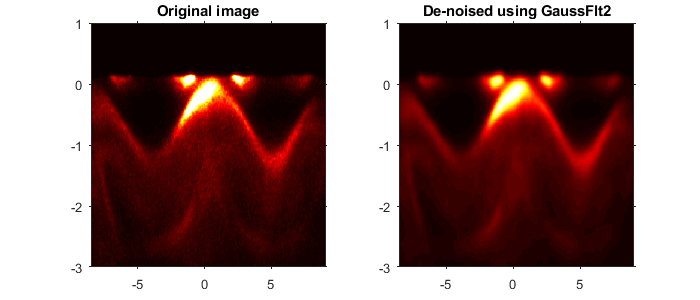

DNDataFrame=GaussFlt2(ContDataFrame,15,15,40,40);

figure;subplot(121);ImData(Angle,Energy,ContDataFrame,'Flat');
colormap hot; set(gca,'TickDir','Out'); limit=[-3,1]; ylim(limit);
title('Original image')

subplot(122); ImData(Angle,Energy,DNDataFrame,'Flat');
colormap hot; set(gca,'TickDir','Out'); ylim(limit)
title('De-noised using GaussFlt2'); set(gcf,'Position',[0,0,700,300])

Subtracting an angle-integrated spectrum removes non-dispersive features from the data. The integration can be performed using *IntAngle.*

Note that the contrast was also adjusted in the example below.

DataInt=IntAngle(DataFrame,Angle,Energy);

- Angle integrating


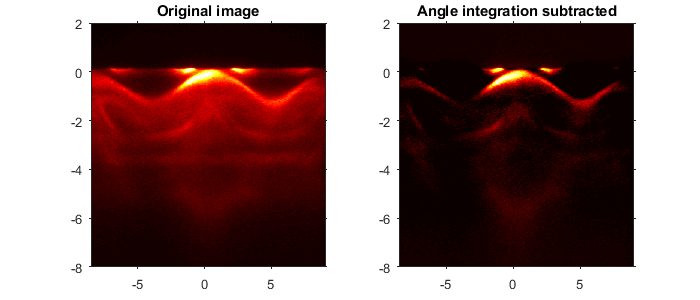

NormData=DataFrame-DataInt;

NormData=SetContrast(NormData,0.15,1.);
figure;subplot(121);ImData(Angle,Energy,DataFrame,'Flat');
colormap hot; set(gca,'TickDir','Out');ylim(limit2)

title('Original image');
subplot(122);ImData(Angle,Energy,NormData,'Flat');
colormap hot; ylim(limit2)
title('Angle integration subtracted'); set(gcf,'Position', [0,0,700,300])

## Cuts and Slices

MATools also provides functions for cutting and slicing the data along planes of both constant energy or angle/k.

Below we create and display an iso-energy surface for the different tilt angles. Iso-angle slices can be performed using the 'IsoK' option in the *Slice* function instead of 'IsoE'.

EWindow=[-1.05 -0.95];
[ASlice, XSlice]=Slice(Angle,Energy,Data,'IsoE',EWindow);

- Data slice formation


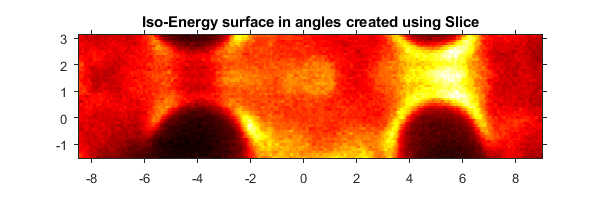

figure; ImData(XSlice,Scan,ASlice,'Flat');
colormap hot; set(gca,'TickDir','Out');set(gcf, 'Position',[0,0,600,200]);
axis equal tight;
title('Iso-Energy surface in angles created using Slice')

Performing cuts is accomplished using the *Cut* function in very similar syntax to *Slice*. Note however that *Cut* requires 2D inputs and returns 1D output. Here, we perform a constant k cut through our previously selected frame and display it using the standard *plot* function. Energy cuts may be performed using the 'MDC' option.

KWindow=[2.5,2.55]; [ACut, XCut] = Cut(Angle,Energy,DataFrame,'EDC',KWindow);

- Data cut formation


figure;subplot(122);plot(ACut, XCut,'r'); 
title('Constant-angle cut performed using Cut');axis square; xlim(limit)

Additional features may be drawn into the *ImData* figure using *hold* as usual. Here, we include the location of the cut in white on our original frame.

subplot(121); ImData(Angle,Energy,DataFrame,'Flat'); ylim(limit)
colormap hot; set(gca,'TickDir','Out'); hold;

Current plot held


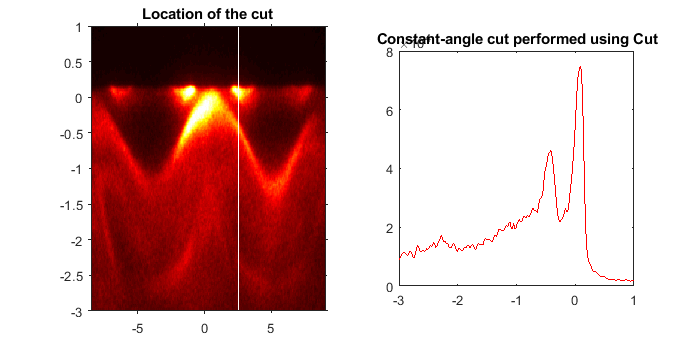

plot([mean(KWindow),mean(KWindow)], [min(Energy(:)),max(Energy(:))],'w-');
title('Location of the cut'); set(gcf, 'Position',[0,0,700,350])

## Edge Detection

MATools provides two methods of edge detection in the data.

The first, *LaplaceFlt2*, calculates the Laplacian of '2nd' (default) or '4th' order of the data.

LpFrame=GaussFlt2(DataFrame,15,15,40,40);
LpFrame=SetContrast(LpFrame,0.4,0.999,1.5);
LpFrame = LaplaceFlt2(LpFrame);

figure; subplot(311); ImData(Angle,Energy,DataFrame,'Flat');
colormap hot; set(gca,'TickDir','Out');ylim(limit)
title('Original image');

subplot(312);ImData(Angle, Energy, LpFrame,'Flat');
colormap hot; set(gca,'TickDir','Out');ylim(limit)
title('Edge detection using LaplaceFlt2');

The second, *CurvatureFlt2*, calculates the '1D' or '2D' curvature of the data as described in Review of Scientific Instruments **82**, 043712 (2011); [https://doi.org/10.1063/1.3585113](https://doi.org/10.1063/1.3585113). Note that noise filtering might be necessary both before and after using *CurvatureFlt2* to produce usable results.

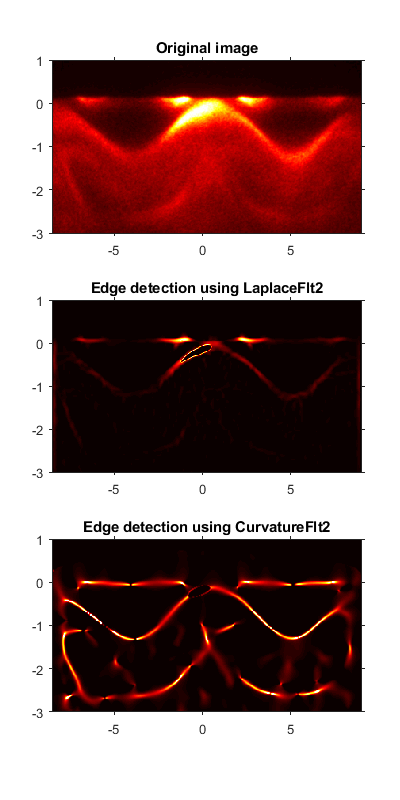

CrvFrame=GaussFlt2(DataFrame,100,100,500,500);
CrvFrame=SetContrast(CrvFrame,0.4,0.999,1.5);

CrvFrame=CurvatureFlt2(CrvFrame,'2D',1,1);

CrvFrame=GaussFlt2(CrvFrame,1,1,10,10);
CrvFrame=SetContrast(CrvFrame,0.2,0.999);

subplot(313);ImData(Angle, Energy, CrvFrame,'Flat');
colormap hot; set(gca,'TickDir','Out');ylim(limit);
title('Edge detection using CurvatureFlt2');
set(gcf, 'Position', [0, 0, 400, 800])